# Teoria de Errores y Cifras Significativas con Series de Maclaurin

Dr. Hermes Pantoja Carhuavilca

## Enunciado

La **serie de Maclaurin** es una representación de funciones en forma de una suma infinita de términos calculados a partir de las derivadas de la función en un punto específico (en este caso, $0$). La serie de Maclaurin para la función $\cos (x)$ está dada por:


$$\cos(x) = \sum_{n=0}^{\infty} \frac{(-1)^n x^{2n}}{(2n)!}$$


Queremos aproximar el valor de $\cos (x)$ utilizando un número finito de términos de esta serie.

**Datos:**

- Valor de $x=0.3\pi$

### Objetivo

- Determinar el **número mínimo de términos** necesarios en la serie de Maclaurin para aproximar $\cos (0.3\pi )$con **8 cifras significativas**.

- Implementar esta aproximación en **MATLAB** utilizando un **Live Script**.

- Utilizar un **slider interactivo** para visualizar cómo el número de términos afecta la precisión de la aproximación.

- Calcular y visualizar el **error relativo** asociado a cada aproximación.

### Conceptos Teóricos

#### Serie de Maclaurin para $\cos(x)$

La serie de Maclaurin es una expansión en serie de una función en torno a $x = 0$. Para la función $\cos(x)$, la serie de Maclaurin está dada por: 


$$\cos(x) = \sum_{n=0}^{\infty} \frac{(-1)^n x^{2n}}{(2n)!} = 1 - \frac{x^2}{2!} + \frac{x^4}{4!} - \frac{x^6}{6!} + \cdots$$


 Esta serie se utiliza para aproximar el valor de $\cos(x)$ utilizando un número finito de términos.

#### Cifras Significativas y Error Relativo

Cuando realizamos aproximaciones numéricas, es importante evaluar cuán preciso es el resultado obtenido. Las **cifras significativas** son los dígitos en un número que contribuyen a su precisión. Para determinar si una aproximación tiene $n$ cifras significativas, utilizamos el concepto de **error relativo**. El  **error relativo**  $\delta_r$ se define como: 


$$\delta_r = \left| \frac{\text{Valor real} - \text{Valor aproximado}}{\text{Valor real}} \right|$$
 

Para que una aproximación tenga $n$ cifras significativas, el error relativo debe cumplir con la siguiente condición:

 
$$\delta_r \leq 5 \times 10^{-n}$$
 

Por ejemplo, para obtener **8 cifras significativas**, el error relativo debe ser menor o igual a $5 \times 10^{-8}$.

### Preguntas

- ¿Cuántos términos de la serie de Maclaurin se requieren para aproximar $\cos(0.3\pi)$ con una precisión de 8 cifras significativas?

- Desarrolle un script en MATLAB que:

- Calcule la aproximación de $\cos (0.3\pi )$ usando la serie de Maclaurin con el número mínimo de términos encontrado.

- Calcule el **error relativo** de la aproximación.

- Incluya un **slider interactivo** que permita variar el número de términos de la serie y observe cómo afecta la aproximación y el error relativo.

- Presente los resultados de manera clara y concisa, mostrando el valor aproximado y el error relativo correspondiente.

### Solución

% Valor de x
format long
valor = 0.3 * pi;

% Valor real de cos(x)
valor_real = cos(valor)

valor_real =    0.587785252292473



condicion = 5e-8 % Condición para 8 cifras significativas

condicion =      5.000000000000000e-08




k=12

k =     12



syms x
f=cos(x)

$$f = \cos\left(x\right)$$

Tk = taylor(f,x,'Order',k)

$$Tk = -\frac{x^{10}}{3628800}+\frac{x^{8}}{40320}-\frac{x^{6}}{720}+\frac{x^{4}}{24}-\frac{x^{2}}{2}+1$$

Tk_fu=matlabFunction(Tk)

Tk_fu = function_handle with value:
    @(x)x.^2.*(-1.0./2.0)+x.^4./2.4e+1-x.^6./7.2e+2+x.^8./4.032e+4-x.^10./3.6288e+6+1.0


cos_aprox=Tk_fu(valor)

cos_aprox =    0.587785251272005



% Cálculo del error relativo
error_relativo = abs((valor_real - cos_aprox) / valor_real)

error_relativo =      1.736124876443481e-09



% Verificación de la condición de error
if error_relativo <= condicion
        fprintf('Se requieren %d términos para alcanzar 8 cifras significativas.\n', k)
        fprintf('Valor aproximado: %.10f\n', cos_aprox)
        fprintf('Error relativo: %.10e\n', error_relativo)
end

Se requieren 12 términos para alcanzar 8 cifras significativas.


Valor aproximado: 0.5877852513


Error relativo: 1.7361248764e-09


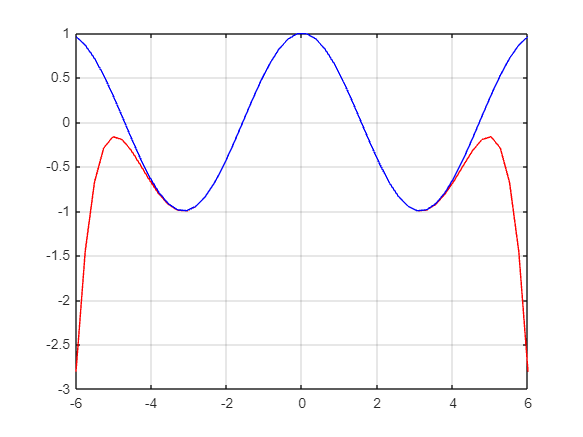


%Gráfica de la función cos(x) vs función aproximada

xx=linspace(-6,6,50);
yy1=Tk_fu(xx);
plot(xx,yy1,'r',xx,cos(xx),'b')
grid on